clc; clear; close all

[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

## Random SE3

T(:,:,1) = randSE3(pi,20);
T(:,:,2) = randSE3(pi,20);

## Get Screw Motion Data

min_ag = [5,2]/180*pi;
axis_length = 1;
plotdata = GetScrewPlotData(T(:,:,1),T(:,:,2),min_ag,axis_length);

fields = fieldnames(plotdata);
for i = 1:numel(fields)
    assignin('base', fields{i}, plotdata.(fields{i}));
end

## Plot Screw Motion

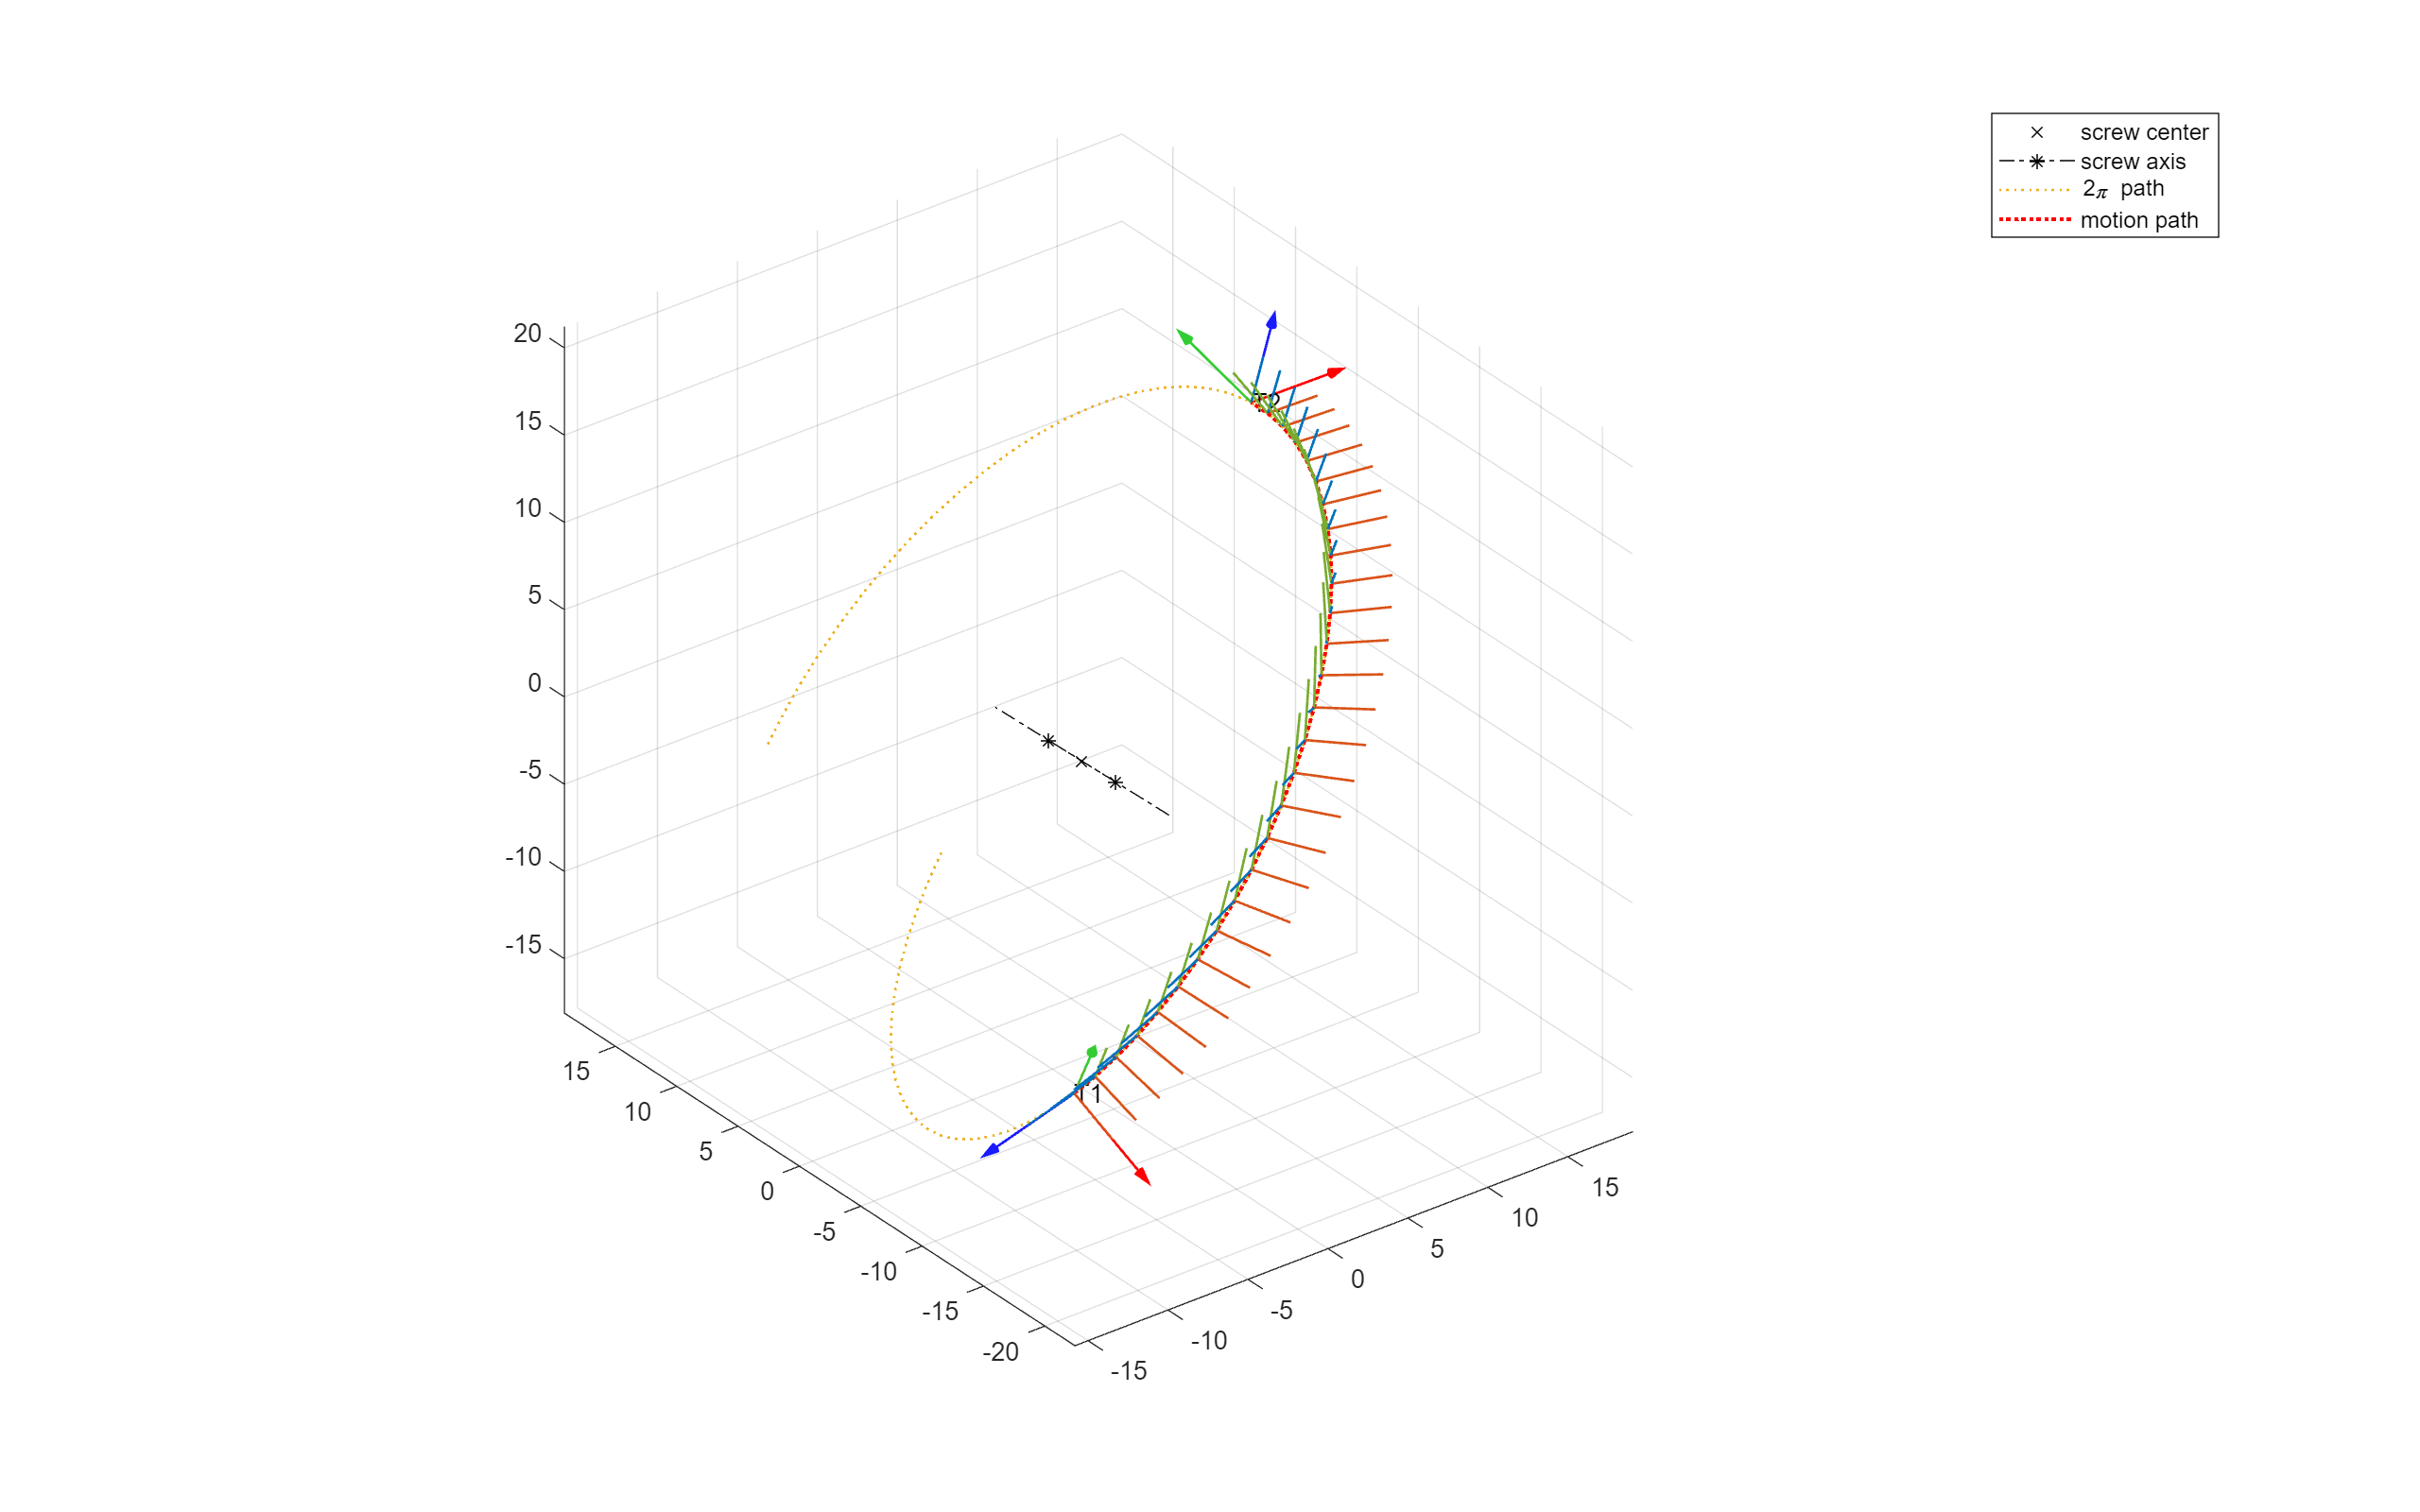

dist = norm(T(1:3,4,1)-T(1:3,4,2));
scale = dist/6;

f = figure;
for i = 1:2
    PlotFrame(T(:,:,i),'scale',scale,'linewidth',1,...
        'style','-','colorind',1,'arrowsize',1/6,'text','off');hold on
    text(T(1,4,i),T(2,4,i),T(3,4,i),['T',num2str(i)])
end

for i = 1:size(Frames,3)
    PlotFrame(Frames(:,:,i),'scale',scale/2,'linewidth',1,...
        'style','-','colorind',2,'text','off');hold on    
end

p(1) = plot3(Center(1),Center(2),Center(3),'xk'); hold on
p(2) = plot3(ProjPt(1,:),ProjPt(2,:),ProjPt(3,:),'*-.k'); hold on
plot3(Axis(1,:),Axis(2,:),Axis(3,:),'-.k'); hold on
p(3) = plot3(FPath(1,:),FPath(2,:),FPath(3,:),':','LineWidth',1,'Color',[0.9290 0.6940 0.1250]);
p(4) = plot3(Path(1,:),Path(2,:),Path(3,:),':r','LineWidth',1.5);
legend(p,{'screw center','screw axis','2\pi path','motion path'})
grid on; axis equal; 
set(f,'Units','normalized','Position',[0,0,1,1])